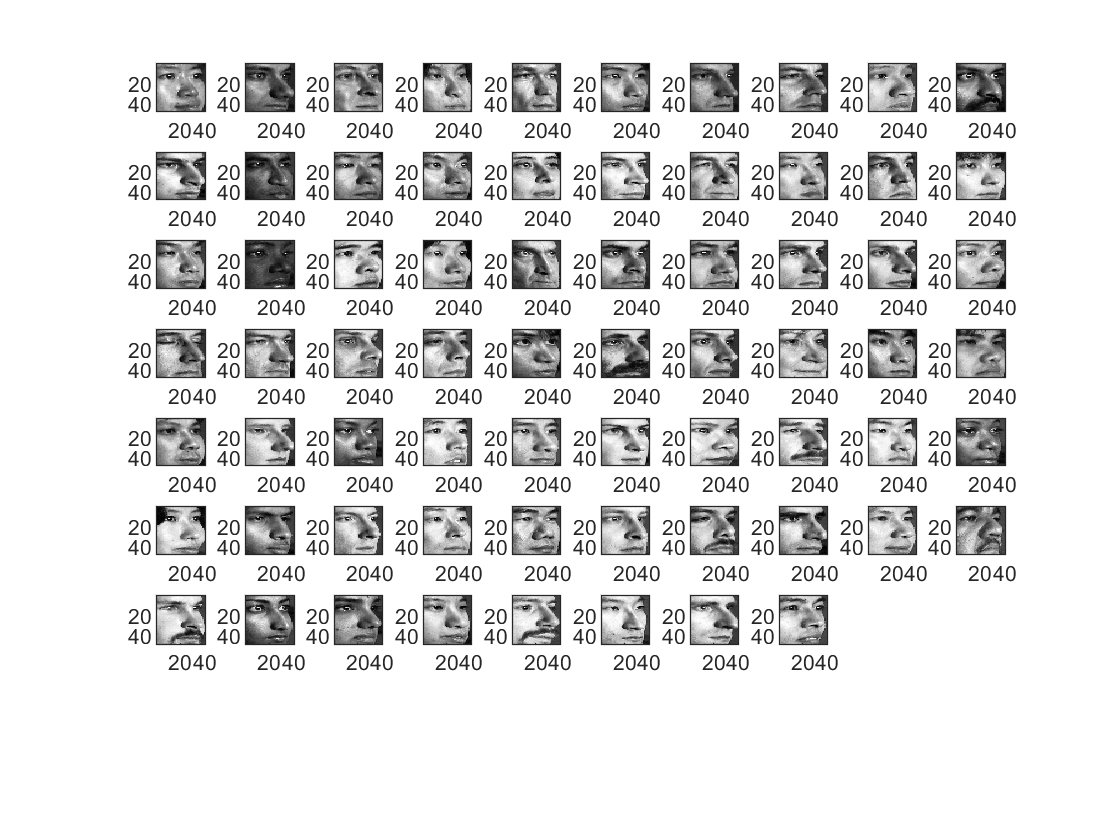

%Initializing and loading datasets
data = load('pose.mat');
pose = data.pose;
% Each image is 48x40 pixel image, there are 13 images for each subject and 68 subjects
figure, clf;
colormap 'gray';
%display the 1st image of each subject
for i=1:68
    subplot(8,10,i);
    imagesc(pose(:,:,1,i)); 
end

## Prepare Train and Test datasets

Using the 1st 10 images for training pupose and testing on remaining 3 for each subject.

trn_sz = 10;
X_trn=zeros(size(pose,1), size(pose,2),1,trn_sz*size(pose,4));
Y_trn=zeros(trn_sz*size(pose,4),1);
for i=1:size(pose,4)
    for j=1:trn_sz
        X_trn(:,:,1,(i-1)*trn_sz + j) = pose(:,:,j,i);
        Y_trn((i-1)*trn_sz + j) = i;
    end
end
X_tst=zeros(size(pose,1), size(pose,2),1,(size(pose,3)-trn_sz)*size(pose,4));
Y_tst=zeros((size(pose,3)-trn_sz)*size(pose,4),1);
for i=1:size(pose,4)
    for j=trn_sz + 1:size(pose,3)
        X_tst(:,:,1,(i-1)*(size(pose,3)-trn_sz)+j-trn_sz) = pose(:,:,j,i);
        Y_tst((i-1)*(size(pose,3)-trn_sz)+j-trn_sz) = i;
    end
end
Y_trn = categorical(Y_trn);
Y_tst = categorical(Y_tst);

% Running a simple convolutional neytwork on different optimizers, batch
% sizes, learning rates, etc. to optimize the hyperparameters
options = trainingOptions('sgdm', ...
    'MaxEpochs',20,...
    'InitialLearnRate',1e-3,...
    'MiniBatchSize',20,...
    'ValidationData',{X_tst,Y_tst},...
    'Shuffle',"every-epoch",...
    'Verbose',true, ...
    'Plots','training-progress');

layers = [ ...
    imageInputLayer([48 40 1])
    convolution2dLayer(5,20)
    batchNormalizationLayer
    reluLayer
%    averagePooling2dLayer(3)
    maxPooling2dLayer(2,'Stride',2)
    convolution2dLayer(3,32)
    batchNormalizationLayer
    reluLayer
% %    averagePooling2dLayer(3)
    maxPooling2dLayer(2,'Stride',1)
    fullyConnectedLayer(68)
    softmaxLayer
    classificationLayer];
[net, info] = trainNetwork(X_trn,Y_trn,layers,options);

Training on single CPU.
Initializing input data normalization.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:07 |        0.00% |        1.47% |       5.9201 |       5.1858 |          0.0010 |


|       2 |          50 |       00:00:13 |       45.00% |       26.47% |       1.9068 |       3.0258 |          0.0010 |


|       3 |         100 |       00:00:19 |       70.00% |       49.51% |       0.9040 |       1.9238 |          0.0010 |


|       5 |         150 |       00:00:25 |      100.00% |       58.82% |       0.2967 |       1.5545 |          0.0010 |


|       6 |         200 |       00:00:31 |      100.00% |       68.14% |       0.1173 |       1.3357 |          0.0010 |


|       8 |         250 |       00:00:37 |      100.00% |       67.16% |       0.0598 |       1.2766 |          0.0010 |


|       9 |         300 |       00:00:43 |      100.00% |       72.06% |       0.1095 |       1.1789 |          0.0010 |


|      11 |         350 |       00:00:49 |      100.00% |       69.61% |       0.0605 |       1.2222 |          0.0010 |


|      12 |         400 |       00:00:55 |      100.00% |       70.59% |       0.0296 |       1.1645 |          0.0010 |


|      14 |         450 |       00:01:01 |      100.00% |       69.61% |       0.0251 |       1.2009 |          0.0010 |


|      15 |         500 |       00:01:06 |      100.00% |       73.53% |       0.0229 |       1.1359 |          0.0010 |


|      17 |         550 |       00:01:13 |      100.00% |       74.02% |       0.0189 |       1.1071 |          0.0010 |


|      18 |         600 |       00:01:19 |      100.00% |       71.57% |       0.0241 |       1.1015 |          0.0010 |


|      20 |         650 |       00:01:25 |      100.00% |       71.08% |       0.0316 |       1.1720 |          0.0010 |


|      20 |         680 |       00:01:28 |      100.00% |       72.55% |       0.0137 |       1.1240 |          0.0010 |
|======================================================================================================================|


Y_pred = classify(net,X_tst);
accuracy = sum(Y_pred == Y_tst)/size(Y_tst,1)

accuracy = 0.7353

% Running the Resnet18 architecture with the best optimized hyperparameters
options = trainingOptions('adam', ...
    'MaxEpochs',10,...
    'InitialLearnRate',1e-3,...
    'MiniBatchSize',20,...
    'ValidationData',{X_tst,Y_tst},"LearnRateDropFactor",0.9,...
    'Shuffle',"every-epoch",...
    'Verbose',true, ...
    'Plots','training-progress');
rpose = resnet18("Weights","none"); 
rpose = rpose.replaceLayer('data',imageInputLayer([48 40 1],'Name','Input'));
rpose = rpose.replaceLayer('fc1000',fullyConnectedLayer(68,"Name","connect"));

[r_pose, r_info] = trainNetwork(X_trn,Y_trn,rpose,options);

Training on single CPU.
Initializing input data normalization.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:11 |        5.00% |        4.90% |       4.8545 |       4.7095 |          0.0010 |


|       2 |          50 |       00:01:10 |       15.00% |       31.37% |       3.0779 |       2.5303 |          0.0010 |


|       3 |         100 |       00:02:11 |       35.00% |       49.02% |       1.8002 |       1.6622 |          0.0010 |


|       5 |         150 |       00:03:14 |       85.00% |       58.82% |       0.5461 |       1.6238 |          0.0010 |


|       6 |         200 |       00:04:15 |       95.00% |       68.14% |       0.2537 |       1.2038 |          0.0010 |


|       8 |         250 |       00:05:19 |       95.00% |       61.27% |       0.1677 |       1.4554 |          0.0010 |


|       9 |         300 |       00:06:20 |       95.00% |       69.12% |       0.2119 |       1.2264 |          0.0010 |


|      10 |         340 |       00:07:18 |      100.00% |       71.08% |       0.1018 |       1.1162 |          0.0010 |
|======================================================================================================================|


Y_pred = classify(r_pose,X_tst);
accuracy = sum(Y_pred == Y_tst)/size(Y_tst,1)

accuracy = 0.6863

% Next I'll run the another benchmark architecture- Alexnet
anet = alexnet('Weights','none');
%analyzeNetwork(anet)
options = trainingOptions('sgdm', ...
    'MaxEpochs',40,...
    'InitialLearnRate',1e-3,...
    'MiniBatchSize',20,...
    'ValidationData',{X_tst,Y_tst},...
    'Shuffle',"every-epoch",...
    'Verbose',true, ...
    'Plots','training-progress');
layers = [...
    imageInputLayer([48 40 1])
    anet(2:3)
    batchNormalizationLayer
    anet(6:7)
    batchNormalizationLayer
    anet(16)
    anet(end-5:end-3)
    fullyConnectedLayer(68,"Name","connect")
    softmaxLayer("Name","prob")
    classificationLayer("Name","final")];
[a_net, a_info] = trainNetwork(X_trn,Y_trn,layers,options);

Training on single CPU.
Initializing input data normalization.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:09 |        0.00% |        2.45% |       7.7671 |       5.1681 |          0.0010 |


|       2 |          50 |       00:00:24 |       15.00% |       19.12% |       4.0187 |       3.5456 |          0.0010 |


|       3 |         100 |       00:00:39 |       45.00% |       34.31% |       2.6936 |       2.5263 |          0.0010 |


|       5 |         150 |       00:00:53 |       60.00% |       40.69% |       1.4159 |       2.4333 |          0.0010 |


|       6 |         200 |       00:01:09 |       75.00% |       48.53% |       1.2221 |       1.9286 |          0.0010 |


|       8 |         250 |       00:01:23 |       80.00% |       56.86% |       0.6341 |       1.6717 |          0.0010 |


|       9 |         300 |       00:01:37 |       95.00% |       57.35% |       0.2129 |       1.4902 |          0.0010 |


|      11 |         350 |       00:01:53 |       95.00% |       64.22% |       0.0900 |       1.4332 |          0.0010 |


|      12 |         400 |       00:02:08 |      100.00% |       63.73% |       0.0947 |       1.4443 |          0.0010 |


|      14 |         450 |       00:02:25 |      100.00% |       71.57% |       0.0512 |       1.2367 |          0.0010 |


|      15 |         500 |       00:02:42 |      100.00% |       69.61% |       0.0267 |       1.2072 |          0.0010 |


|      17 |         550 |       00:03:00 |      100.00% |       70.10% |       0.0481 |       1.1557 |          0.0010 |


|      18 |         600 |       00:03:17 |       95.00% |       69.12% |       0.1284 |       1.1860 |          0.0010 |


|      20 |         650 |       00:03:35 |      100.00% |       72.06% |       0.0223 |       1.1631 |          0.0010 |


|      21 |         700 |       00:03:55 |      100.00% |       72.55% |       0.0168 |       1.1222 |          0.0010 |


|      23 |         750 |       00:04:15 |      100.00% |       71.57% |       0.0080 |       1.0920 |          0.0010 |


|      24 |         800 |       00:04:33 |       95.00% |       71.57% |       0.0921 |       1.1387 |          0.0010 |


|      25 |         850 |       00:04:56 |      100.00% |       73.53% |       0.0155 |       1.0666 |          0.0010 |


|      27 |         900 |       00:05:14 |      100.00% |       70.59% |       0.0183 |       1.1345 |          0.0010 |


|      28 |         950 |       00:05:32 |      100.00% |       73.04% |       0.0302 |       1.1582 |          0.0010 |


|      30 |        1000 |       00:05:50 |      100.00% |       73.04% |       0.0123 |       1.1340 |          0.0010 |


|      31 |        1050 |       00:06:11 |      100.00% |       72.55% |       0.0116 |       1.1011 |          0.0010 |


|      33 |        1100 |       00:06:29 |      100.00% |       72.06% |       0.0176 |       1.1071 |          0.0010 |


|      34 |        1150 |       00:06:47 |      100.00% |       73.53% |       0.0032 |       1.0791 |          0.0010 |


|      36 |        1200 |       00:07:05 |      100.00% |       72.06% |       0.0041 |       1.1441 |          0.0010 |


|      37 |        1250 |       00:07:23 |      100.00% |       73.53% |       0.0031 |       1.0661 |          0.0010 |


|      39 |        1300 |       00:07:42 |       95.00% |       73.53% |       0.1750 |       1.0962 |          0.0010 |


|      40 |        1350 |       00:08:01 |      100.00% |       74.51% |       0.0056 |       1.0603 |          0.0010 |


|      40 |        1360 |       00:08:05 |      100.00% |       73.04% |       0.0084 |       1.1309 |          0.0010 |
|======================================================================================================================|


Y_pred = classify(a_net,X_tst);
accuracy = sum(Y_pred == Y_tst)/size(Y_tst,1)

accuracy = 0.7353

% Next trying another pre-trained available architecture - Resnet50 with the same hyperparameters.
rnet50 = resnet50("Weights","none"); 
rnet50 = rnet50.replaceLayer('input_1',imageInputLayer([48 40 1],'Name','Input'));
rnet50 = rnet50.replaceLayer('fc1000',fullyConnectedLayer(68,"Name","connect"));
[r_net50, r_info50] = trainNetwork(X_trn,Y_trn,rnet50,options);

Training on single CPU.
Initializing input data normalization.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:27 |        0.00% |        0.98% |       5.7792 |       5.6261 |          0.0010 |


|       2 |          50 |       00:03:09 |        5.00% |        5.39% |       4.3546 |       4.4656 |          0.0010 |


|       3 |         100 |       00:05:40 |       35.00% |       14.22% |       2.5461 |       3.7411 |          0.0010 |


|       5 |         150 |       00:08:14 |       35.00% |       24.02% |       1.7959 |       3.3340 |          0.0010 |


|       6 |         200 |       00:10:40 |       60.00% |       25.98% |       1.3635 |       3.1980 |          0.0010 |


|       8 |         250 |       00:13:07 |       75.00% |       32.84% |       0.6328 |       2.7868 |          0.0010 |


|       9 |         300 |       00:15:39 |       85.00% |       32.35% |       0.4576 |       2.7936 |          0.0010 |


|      11 |         350 |       00:18:09 |       90.00% |       39.22% |       0.2213 |       2.4900 |          0.0010 |


|      12 |         400 |       00:20:38 |       95.00% |       40.20% |       0.1040 |       2.3614 |          0.0010 |


|      14 |         450 |       00:23:08 |      100.00% |       39.22% |       0.0243 |       2.4482 |          0.0010 |


|      15 |         500 |       00:25:23 |      100.00% |       47.55% |       0.0232 |       2.2581 |          0.0010 |


|      17 |         550 |       00:27:38 |      100.00% |       47.55% |       0.0258 |       2.2703 |          0.0010 |


|      18 |         600 |       00:29:48 |       90.00% |       49.51% |       0.1994 |       2.2162 |          0.0010 |


|      20 |         650 |       00:31:59 |      100.00% |       40.20% |       0.0081 |       2.4090 |          0.0010 |


|      21 |         700 |       00:34:09 |      100.00% |       44.61% |       0.0109 |       2.3300 |          0.0010 |


|      23 |         750 |       00:36:19 |      100.00% |       40.20% |       0.0090 |       2.4100 |          0.0010 |


|      24 |         800 |       00:38:33 |      100.00% |       49.02% |       0.0230 |       2.1026 |          0.0010 |


|      25 |         850 |       00:40:41 |      100.00% |       48.04% |       0.0358 |       2.1808 |          0.0010 |


|      27 |         900 |       00:42:53 |      100.00% |       48.53% |       0.0106 |       2.3521 |          0.0010 |


|      28 |         950 |       00:45:07 |      100.00% |       49.02% |       0.0120 |       2.2347 |          0.0010 |


|      30 |        1000 |       00:47:18 |      100.00% |       51.47% |       0.0156 |       2.0756 |          0.0010 |


|      31 |        1050 |       00:49:29 |      100.00% |       47.55% |       0.0063 |       2.3098 |          0.0010 |


|      33 |        1100 |       00:51:40 |      100.00% |       48.53% |       0.0021 |       2.3060 |          0.0010 |


|      34 |        1150 |       00:54:03 |      100.00% |       49.02% |       0.0053 |       2.0629 |          0.0010 |


|      36 |        1200 |       00:56:05 |      100.00% |       48.53% |       0.0026 |       2.0906 |          0.0010 |


|      37 |        1250 |       00:58:08 |      100.00% |       49.51% |       0.0013 |       2.1068 |          0.0010 |


|      39 |        1300 |       01:00:07 |      100.00% |       53.92% |       0.0022 |       2.1000 |          0.0010 |


|      40 |        1350 |       01:02:07 |      100.00% |       50.00% |       0.0170 |       2.1786 |          0.0010 |


|      40 |        1360 |       01:02:37 |      100.00% |       51.47% |       0.0026 |       2.1577 |          0.0010 |
|======================================================================================================================|


Y_pred = classify(r_net50,X_tst);
accuracy = sum(Y_pred == Y_tst)/size(Y_tst,1)

accuracy = 0.4265